**Spliting Data from Previously normalized data**

data_bayesian=cat(2,x2,y2);
training_set=data_bayesian(tr_lm.trainInd,:);
validation_set=data_bayesian(tr_lm.valInd,:);
x2_bay_training=training_set(:,1:5);
y2_bay_training=training_set(:,6:7);
x2_bay_val=validation_set(:,1:5);
y2_bay_val=validation_set(:,6:7);

**Bayesian regulation**

xt_bay_train=x2_bay_training';
yt_bay_train=y2_bay_training';
xt_bay_val=x2_bay_val';
yt_bay_val=y2_bay_val';
hiddenLayerSize=50;
bay=fitnet(hiddenLayerSize,'trainbr');
bay.divideParam.trainRatio=100/100;
bay.divideParam.valRatio=0/100;
bay.divideParam.testRatio=0/100;
tic
[bay,tr_bay]=train(bay,xt_bay_train,yt_bay_train);
T_b=toc

**Performence**

training set

Y_bay=bay(xt_bay_train);
Yt_bay=yt_bay_train;
yTrain_bay=(Y_bay'.*(max(y)-min(y))+min(y))';
yTrainTrue_bay=(Yt_bay'.*(max(y)-min(y))+min(y))';
perf_P_bay=rMetrics(yTrainTrue_bay(1,:),yTrain_bay(1,:));
perf_Nu_bay=rMetrics(yTrainTrue_bay(2,:),yTrain_bay(2,:));
row_names_bay=array2table({'Pressure_ratio';'Nusselt ratio'});
T_bay_train=cat(1,perf_P_bay,perf_Nu_bay);
T_bay_train=cat(2,row_names_bay,T_bay_train)

T_bay_train = 2×6 table
           Var1             mae          mse          rmse        Rsq       mape 
    __________________    ________    __________    ________    _______    ______

    {'Pressure_ratio'}     0.01427    0.00040791    0.020197    0.99664    1.2306
    {'Nusselt ratio' }    0.010961    0.00024901     0.01578    0.98914    1.2746


Validation set

Y_val_bay=bay(xt_bay_val);
Yt_val_bay=yt_bay_val;
yVal_bay=(Y_val_bay'.*(max(y)-min(y))+min(y))';
yValTrue_bay=(Yt_val_bay'.*(max(y)-min(y))+min(y))';
perf_P_bay=rMetrics(yValTrue_bay(1,:),yVal_bay(1,:));
perf_Nu_bay=rMetrics(yValTrue_bay(2,:),yVal_bay(2,:));
row_names_bay=array2table({'Pressure_ratio';'Nusselt ratio'});
T_bay_val=cat(1,perf_P_bay,perf_Nu_bay);
T_bay_val=cat(2,row_names_bay,T_bay_val)

T_bay_val = 2×6 table
           Var1             mae          mse          rmse        Rsq       mape 
    __________________    ________    __________    ________    _______    ______

    {'Pressure_ratio'}    0.014243     0.0004089    0.020221    0.99598     1.242
    {'Nusselt ratio' }    0.011305    0.00030322    0.017413     0.9867    1.3311


**Plot**

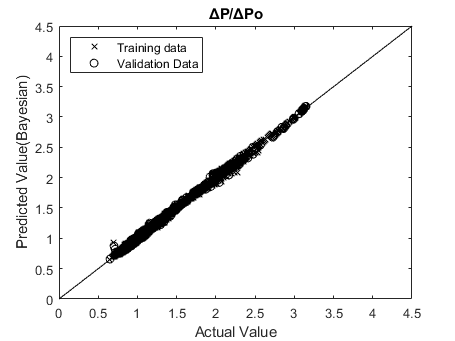

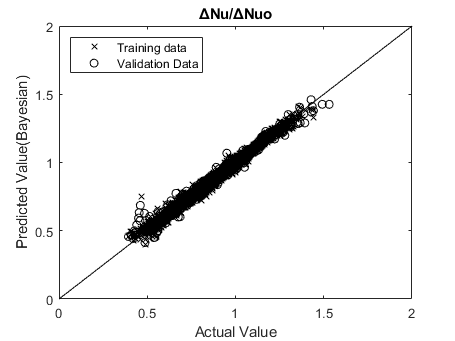

for i=1:2
    figure()
    set(gca,'box','on')
    hold on;
    plot(yTrainTrue_bay(i,:),yTrain_bay(i,:),'x','Color','k');
    plot(yValTrue_bay(i,:),yVal_bay(i,:),'o','Color','k');
    plot(0:5,0:5,'Color','k');
    if i==1
        xlim([0 4.5])
        ylim([0 4.5])
    else
        xlim([0 2])
        ylim([0 2])
    end
    legend('Training data','Validation Data','','Location','northwest')
    xlabel('Actual Value')
    ylabel('Predicted Value(Bayesian)')
    if i==1
        title('ΔP/ΔPo');
    else
        title('ΔNu/ΔNuo');
    end
    hold off;
    if i==1
        Plot_BAY_4=sprintf('D:/Matlab Drive/Research/Figure/BAY/ΔP÷ΔPo.bmp');
        saveas(gcf,Plot_BAY_4)
    else
        Plot_BAY_4=sprintf('D:/Matlab Drive/Research/Figure/BAY/ΔNu÷ΔNuo.bmp');
        saveas(gcf,Plot_BAY_4)
    end
end

**Optimization**

%run to clear previous variable value
clear("rms_train_bay",'rms_val_bay','r2_train_bay',"r2_val_bay",'mape_train_bay',"mape_val_bay",'name_bay')

%select all and press ctrl+T to enable section
hiddenLayerNo=[1,2,3];
for i=1:50
    tic
    %defining the architecture of the Ann
    hiddenLayerSize=i;
    bay=fitnet(hiddenLayerSize,'trainbr');
    %training of Ann
    [bay,tr_bay]=train(bay,xt_bay_train,yt_bay_train,'useParallel','yes');
    T_bay(i,:)=toc
   
    Y_val_bay=bay(xt_bay_val);
    Yt_val_bay=yt_bay_val;
    Y_bay=bay(xt_bay_train);
    Yt_bay=yt_bay_train;

    yTrain_bay=(Y_bay'.*(max(y)-min(y))+min(y))';
    yTrainTrue_bay=(Yt_bay'.*(max(y)-min(y))+min(y))';
    yVal_bay=(Y_val_bay'.*(max(y)-min(y))+min(y))';
    yValTrue_bay=(Yt_val_bay'.*(max(y)-min(y))+min(y))';
    %RMSE
    for j=1:2
        rms_train_bay(i,j)=sqrt(mean(((yTrain_bay(j,:)-yTrainTrue_bay(j,:)).^2),2));
    end   
    for j=1:2
        rms_val_bay(i,j)=sqrt(mean(((yVal_bay(j,:)-yValTrue_bay(j,:)).^2),2));
    end
    %R2
    for j=1:2
        r2_train_bay(i,j)=1 - (sum(((yTrainTrue_bay(j,:) - yTrain_bay(j,:)).^2),2)/sum(((yTrainTrue_bay(j,:) - mean(yTrainTrue_bay(j,:),2)).^2),2));
    end   
    for j=1:2
        r2_val_bay(i,j)=1 - (sum(((yValTrue_bay(j,:) - yVal_bay(j,:)).^2),2)/sum(((yValTrue_bay(j,:) - mean(yValTrue_bay(j,:))).^2),2));
    end
    %mape
    for j=1:2
        mape_train_bay(i,j)=mean(abs((yTrainTrue_bay(j,:)-yTrain_bay(j,:))./yTrainTrue_bay(j,:)),2).*100;
    end   
    for j=1:2
        mape_val_bay(i,j)=mean(abs((yValTrue_bay(j,:)-yVal_bay(j,:))./yValTrue_bay(j,:)),2).*100;
    end

   name_bay{i} = ['Hidden Layer size: ' num2str(i,'%d')];
   Ta_bay=array2table([rms_train_bay T_bay],"VariableNames",{'RMS(delP/delPo)','RMS(delNu/delNuo)','Elapsed Time'});
   Ta_bay.Properties.RowNames=name_bay;
   Tb_bay=array2table([rms_val_bay T_bay],"VariableNames",{'RMS(delP/delPo)','RMS(delNu/delNuo)','Elapsed Time'});
   Tb_bay.Properties.RowNames=name_bay;
end

T_bay = 1.7581

T_bay =     1.7581
    1.8348


T_bay =     1.7581
    1.8348
    5.6071


T_bay =     1.7581
    1.8348
    5.6071
    2.4423


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176
    2.4715


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176
    2.4715


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176
    2.4715


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176
    2.4715


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176
    2.4715


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176
    2.4715


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176
    2.4715


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176
    2.4715


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176
    2.4715


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176
    2.4715


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176
    2.4715


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176
    2.4715


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176
    2.4715


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176
    2.4715


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176
    2.4715


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176
    2.4715


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176
    2.4715


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176
    2.4715


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176
    2.4715


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176
    2.4715


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176
    2.4715


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176
    2.4715


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176
    2.4715


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176
    2.4715


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176
    2.4715


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176
    2.4715


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176
    2.4715


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176
    2.4715


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176
    2.4715


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176
    2.4715


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176
    2.4715


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176
    2.4715


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176
    2.4715


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176
    2.4715


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176
    2.4715


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176
    2.4715


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176
    2.4715


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176
    2.4715


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176
    2.4715


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176
    2.4715


T_bay =     1.7581
    1.8348
    5.6071
    2.4423
    3.1482
    6.2560
    3.1180
    3.0339
    3.7176
    2.4715


%select all and press ctrl+T to enable section
Ta_bay

Ta_bay = 50×3 table
                             RMS(delP/delPo)    RMS(delNu/delNuo)    Elapsed Time
                             _______________    _________________    ____________

    Hidden Layer size: 1         0.32213             0.10867            1.5394   
    Hidden Layer size: 2         0.15373             0.11017            1.7017   
    Hidden Layer size: 3          0.1367             0.10878             1.812   
    Hidden Layer size: 4         0.09927            0.096644            2.9876   
    Hidden Layer size: 5        0.091292            0.085456            4.1818   
    Hidden Layer size: 6         0.11277            0.064203            5.7691   
    Hidden Layer size: 7        0.089656            0.065782            6.7148   
    Hidden L

Tb_bay

Tb_bay = 50×3 table
                             RMS(delP/delPo)    RMS(delNu/delNuo)    Elapsed Time
                             _______________    _________________    ____________

    Hidden Layer size: 1         0.32842             0.11037            1.5394   
    Hidden Layer size: 2         0.15533             0.11205            1.7017   
    Hidden Layer size: 3         0.13706             0.11076             1.812   
    Hidden Layer size: 4         0.10019            0.097126            2.9876   
    Hidden Layer size: 5        0.091808             0.08608            4.1818   
    Hidden Layer size: 6         0.10895            0.064266            5.7691   
    Hidden Layer size: 7        0.090956            0.065613            6.7148   
    Hidden L

writetable(Ta_bay,'D:/Matlab Drive/Research/Table/Performence_bay(training).xlsx','Sheet',1)
writetable(Tb_bay,'D:/Matlab Drive/Research/Table/Performence_bay(validation).xlsx','Sheet',1)

**Select Optimum no of neuron in hidden layer(rmse)**

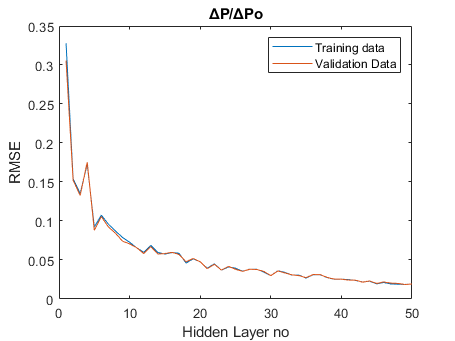

%select all and press ctrl+T to enable section
%for pressure
plot(1:i,rms_train_bay(:,1));hold on;
xlabel('Hidden Layer no')
ylabel('RMSE')
title('ΔP/ΔPo')
plot(1:i,rms_val_bay(:,1));
Plot_BAY_3=sprintf('D:/Matlab Drive/Research/Figure/BAY/ΔP÷ΔPo_optimisation(rmse).bmp');
saveas(gcf,Plot_BAY_3)
legend('Training data','Validation Data');hold off;

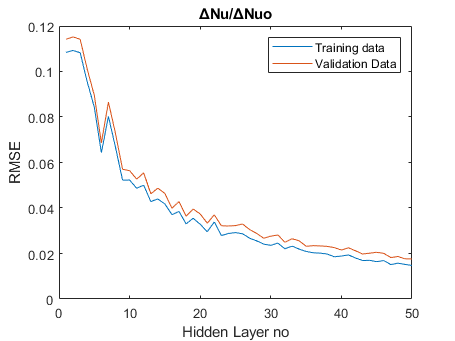

%for nusselt
plot(1:i,rms_train_bay(:,2));hold on;
xlabel('Hidden Layer no')
ylabel('RMSE')
title('ΔNu/ΔNuo')
plot(1:i,rms_val_bay(:,2));
Plot_BAY_3=sprintf('D:/Matlab Drive/Research/Figure/BAY/ΔNu÷ΔNuo_optimisation(rmse).bmp');
saveas(gcf,Plot_BAY_3)
legend('Training data','Validation Data');hold off;

**Select Optimum no of neuron in hidden layer(r2) **

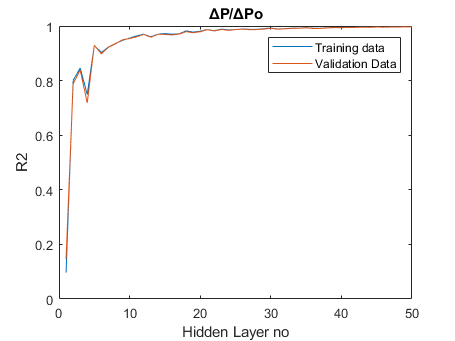

%select all and press ctrl+T to enable section
%for pressure
plot(1:i,r2_train_bay(:,1));hold on;
xlabel('Hidden Layer no')
ylabel('R2')
title('ΔP/ΔPo')
plot(1:i,r2_val_bay(:,1));
Plot_BAY_3=sprintf('D:/Matlab Drive/Research/Figure/BAY/ΔP÷ΔPo_optimisation(r2).bmp');
saveas(gcf,Plot_BAY_3)
legend('Training data','Validation Data');hold off;

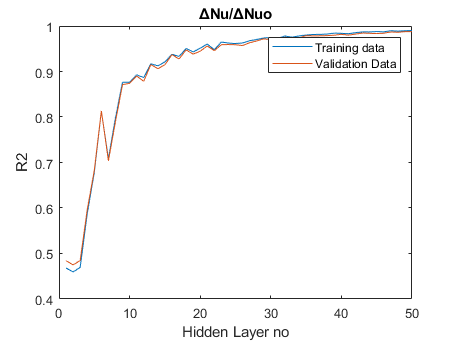

%for nusselt
plot(1:i,r2_train_bay(:,2));hold on;
xlabel('Hidden Layer no')
ylabel('R2')
title('ΔNu/ΔNuo')
plot(1:i,r2_val_bay(:,2));
Plot_BAY_3=sprintf('D:/Matlab Drive/Research/Figure/BAY/ΔNu÷ΔNuo_optimisation(r2).bmp');
saveas(gcf,Plot_BAY_3)
legend('Training data','Validation Data');hold off;

**Select Optimum no of neuron in hidden layer(mape)**

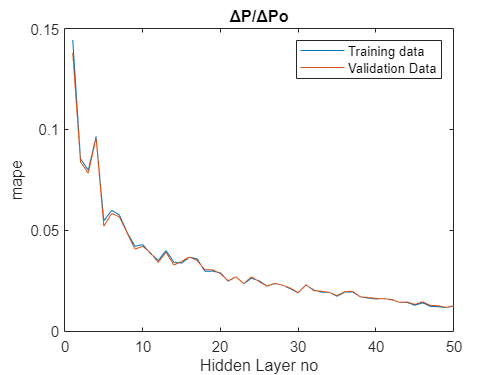

%select all and press ctrl+T to enable section
%for pressure
plot(1:i,mape_train_bay(:,1));hold on;
xlabel('Hidden Layer no')
ylabel('mape')
title('ΔP/ΔPo')
plot(1:i,mape_val_bay(:,1));
Plot_BAY_3=sprintf('D:/Matlab Drive/Research/Figure/BAY/ΔP÷ΔPo_optimisation(mape).bmp');
saveas(gcf,Plot_BAY_3)
legend('Training data','Validation Data');hold off;

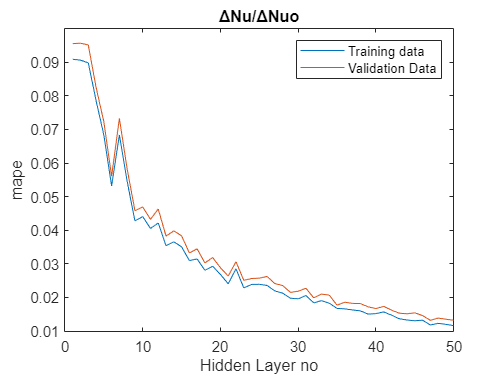

%for nusselt
plot(1:i,mape_train_bay(:,2));hold on;
xlabel('Hidden Layer no')
ylabel('mape')
title('ΔNu/ΔNuo')
plot(1:i,mape_val_bay(:,2));
Plot_BAY_3=sprintf('D:/Matlab Drive/Research/Figure/BAY/ΔNu÷ΔNuo_optimisation(mape).bmp');
saveas(gcf,Plot_BAY_3)
legend('Training data','Validation Data');hold off;